# Latent Variable Example

This example shows the relationship between the X loadings from the SIMPLS algorithm and the latent variables.

Copyright 2022-2023 Battelle Memorial Institute

## Supporting Information

### A Practical Guide to Chemometric Analysis of Optical Spectroscopic Data

Hope E. Lackey,$^{1,2}$ Rachel L. Sell,$^{1}$ Gilbert L. Nelson,$^{3*}$ Thomas A. Bryan,$^{4*}$ Amanda M. Lines,$^{1,2*}$ Samuel A. Bryan,$^{1,2*}$

$^{1}$ Pacific Northwest National Laboratory, 902 Battelle Boulevard, Richland, WA 99352 

$^{2}$ Washington State University, Department of Chemistry, Pullman WA 99164

$^{3}$College of Idaho, Department of Chemistry, 2112 Cleveland Blvd, Caldwell, ID 83605

$^{4}$ The MathWorks, 3 Apple Hill Drive, Natick, MA 01760-2098

*Email: sam.bryan@pnnl.gov Phone 1 509 375 5648; orcid.org/0000-0002-8826-0880

*Email: tbryan@mathworks.com Phone 1 508 647 7669

*Email: amanda.lines@pnnl.gov Phone: 1 509 375 5689

*Email: gnelson@collegeofidaho.edu Phone: 1 208 459 5241

## Concentration Matrix

The concentration matrix $C_\textrm{train}$ contains the percent by weight of each of 20 solutions in the training data.  The columns correspond to benzene, polystyrene, and gasoline.  In this example, you will compute the latent variables for each of the constituents individually by using one column of $C_\textrm{train}$ at a time.  Computing partial least squares (PLS) on one constituent at a time is called PLS1.  Computing PLS on more than one constituent at a time is called PLS2.


$$C_\textrm{train} = %
\begin{array}{rl}%
\begin{array}{c}%
\begin{array}{rrr}%
\textit{benzene} & \textit{polystyrene} & \textit{gasoline} \\%
\end{array}\\%
\left[%
\begin{array}{rrr}%
         0  &       0 & 100.0000\\%
    5.1309  &       0 &  94.8691\\%
   10.0660  &       0 &  89.9300\\%
   20.1799  &       0 &  79.8201\\%
   40.0120  &       0 &  59.9878\\%
   59.9972  &       0 &  40.0028\\%
   79.8412  &       0 &  20.1588\\%
   89.8273  &       0 &  10.1727\\%
  100.0000  &       0 &        0\\%
   90.0264  &  9.9736 &        0\\%
   80.1375  & 19.8625 &        0\\%
   64.9950  & 35.0005 &        0\\%
   21.0228  & 45.9197 &  33.0575\\%
   49.9507  &  5.0599 &  44.9895\\%
   40.0182  & 20.0385 &  39.9433\\%
   40.0154  & 10.0036 &  49.9810\\%
   30.0059  & 10.0282 &  59.9659\\%
   40.0340  & 39.9670 &  19.9990\\%
   49.9393  &  3.3748 &  46.6859\\%
   46.6501  & 13.4658 &  39.8840\\%
\end{array}%
\right]%
\end{array}%
&%
\begin{array}{r}%
\\%
1\\%
2\\%
3\\%
4\\%
5\\%
6\\%
7\\%
8\\%
9\\%
10\\%
11\\%
12\\%
13\\%
14\\%
15\\%
16\\%
17\\%
18\\%
19\\%
20\\%
\end{array}%
\end{array}%
$$


Copyright 2022 Battelle Memorial Institute

Load the napalm data set.

clearvars
load pnnl_napalm_data

n is the number of constituents.

n = size(C_train,2)

n = 3

## PLS1 Without Mean Centering

Compute the X loadings using the SIMPLS algorithm without mean centering the data.  Computing partial least squares (PLS) on one constituent at a time is called PLS1.

Set the number of latent variables.

nLatentVariables = 10;

Set up for plotting.

clf
color = pnnl_colorOrder(n);

For each of the constituents in the columns of  $C_\textrm{train}$, compute the latent variables without mean-centered data using the SIMPLS algorithm.  We're plotting in reverse order so benzene is the top plot.

for k = n:-1:1
    X = A_train;
    Y = C_train(:,k);
    [X_loadings, Y_loadings, X_scores, Y_scores, Weights] = pnnl_simpls(X, Y, nLatentVariables);

The latent variables (LV) are the rectified and normalized X loadings from the SIMPLS algorithm.  The X loadings are column-oriented, so transpose them so the latent variables will be row-oriented.

    LV = pnnl_normalize_rows(pnnl_rectify_rows(X_loadings'));

Plot the first five latent variables.

    h{k} = pnnl_strip_plot(Wavenumbers,LV(1:5,:),'PLS1 Latent Variables Without Mean Centering',WavenumberLabel,'Latent Variable',color(k,:),ConstituentNames{k});
    hold on
end

Turn on the legend for each constituent.

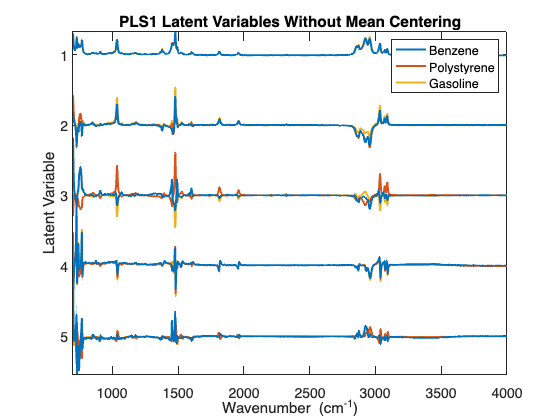

legend([h{1}(1) h{2}(1) h{3}(1)])

## PLS1 With Mean Centering

Compute the X loadings using the SIMPLS algorithm with mean centering the data.  Computing partial least squares (PLS) on one constituent at a time is called PLS1.

Set the number of latent variables.

nLatentVariables = 10;

Set up for plotting.

clf
color = pnnl_colorOrder(n);

For each of the constituents in the columns of  $C_\textrm{train}$, compute the latent variables without mean-centered data using the SIMPLS algorithm.  We're plotting in reverse order so benzene is the top plot.

for k = n:-1:1
    X = A_train;
    Y = C_train(:,k);
    

Mean-center the data.

    X0 = X - mean(X,1);
    Y0 = Y - mean(Y,1);

Compute the loadings using the SIMPLS algorithm.

    [X_loadings, Y_loadings, X_scores, Y_scores, Weights] = pnnl_simpls(X0, Y0, nLatentVariables);

The latent variables (LV) are the rectified and normalized X loadings from the SIMPLS algorithm.  The X loadings are column-oriented, so transpose them so the latent variables will be row-oriented.

    LV = pnnl_normalize_rows(pnnl_rectify_rows(X_loadings'));

Plot the first five latent variables.

    h{k} = pnnl_strip_plot(Wavenumbers,LV(1:5,:),'PLS1 Latent Variables With Mean Centering',WavenumberLabel,'Latent Variable',color(k,:),ConstituentNames{k});
    hold on
end

Turn on the legend for each constituent.

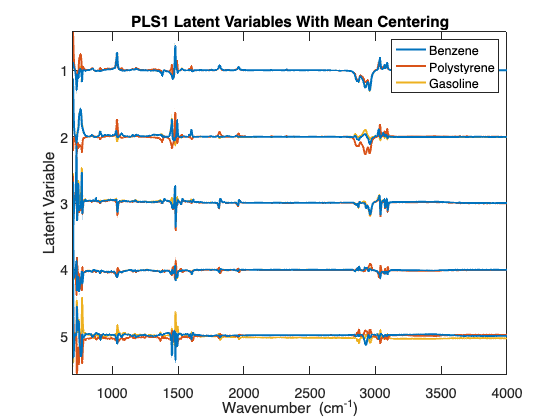

legend([h{1}(1) h{2}(1) h{3}(1)])

## PLS2 Without Mean Centering

Compute the X loadings using the SIMPLS algorithm without mean centering the data.  Computing partial least squares (PLS) on more than one constituent at a time is called PLS2.

Set the number of latent variables.

nLatentVariables = 10;

For all of the constituents in the columns of  $C_\textrm{train}$, compute the latent variables without mean-centered data using the SIMPLS algorithm. 

X = A_train;
Y = C_train;
[X_loadings, Y_loadings, X_scores, Y_scores, Weights] = pnnl_simpls(X, Y, nLatentVariables);

The latent variables (LV) are the rectified and normalized X loadings from the SIMPLS algorithm.  The X loadings are column-oriented, so transpose them so the latent variables will be row-oriented.

LV = pnnl_normalize_rows(pnnl_rectify_rows(X_loadings'));

Plot the first five latent variables.

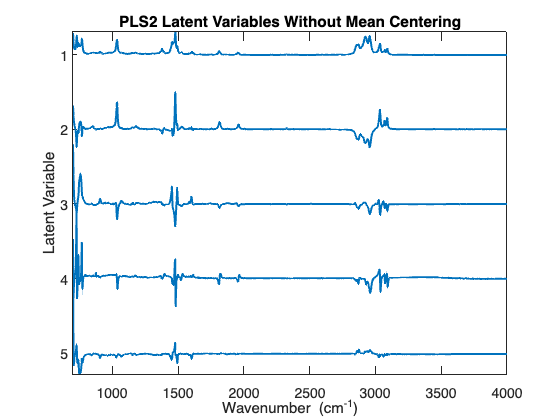

clf
pnnl_strip_plot(Wavenumbers,LV(1:5,:),'PLS2 Latent Variables Without Mean Centering',WavenumberLabel,'Latent Variable');

## PLS2 With Mean Centering

Compute the X loadings using the SIMPLS algorithm without mean centering the data.  Computing partial least squares (PLS) on more than one constituent at a time is called PLS2.

Set the number of latent variables.

nLatentVariables = 10;

For all of the constituents in the columns of  $C_\textrm{train}$, compute the latent variables without mean-centered data using the SIMPLS algorithm. 

X = A_train;
Y = C_train;

Mean-center the data.

    X0 = X - mean(X,1);
    Y0 = Y - mean(Y,1);

Compute the loadings using the SIMPLS algorithm.

[X_loadings, Y_loadings, X_scores, Y_scores, Weights] = pnnl_simpls(X0, Y0, nLatentVariables);

The latent variables (LV) are the rectified and normalized X loadings from the SIMPLS algorithm.  The X loadings are column-oriented, so transpose them so the latent variables will be row-oriented.

LV = pnnl_normalize_rows(pnnl_rectify_rows(X_loadings'));

Plot the first five latent variables.

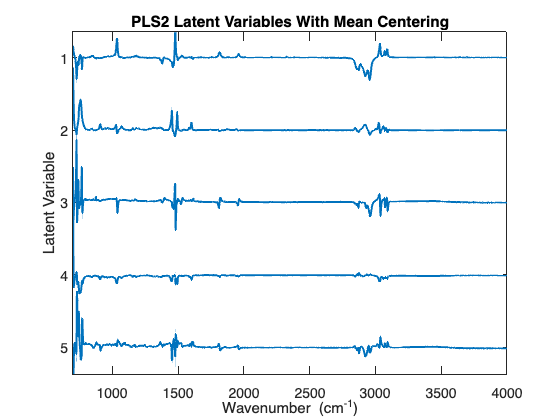

clf
pnnl_strip_plot(Wavenumbers,LV(1:5,:),'PLS2 Latent Variables With Mean Centering',WavenumberLabel,'Latent Variable');

Suppress warning messages.

%#ok<*ASGLU> 

# Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830